clear all;
clf;

## Quadcopter parameters and physical constants

sim_setup.g = 9.81;
sim_setup.quad_mass_kg = 2*24.37E-3 + 2*0.101 + 2*0.051 + 0.15; % mass of arm structures + ESC + motors !!(NEEDS TO CHANGE, PROVIDED BY STRUCTURES)!!
sim_setup.black_mass_kg = 0.06924; % mass of black mounting plate
sim_setup.white_mass_kg = 0.08076; % mass of white plates (plates interacting with lidar sensor)
sim_setup.cart_mass_kg = 0.4;

thrust_data_kgf_W = xlsread('motorspecs.xlsx');
sim_setup.Fit_thrust = fit(thrust_data_kgf_W(:,1), thrust_data_kgf_W(:,2), 'smoothingspline');
sim_setup.Fit_power = fit(thrust_data_kgf_W(:,1), thrust_data_kgf_W(:,3), 'smoothingspline');

sim_setup.k1_m = 0.024 + 0.01184; % CoG of the quadcopter except the cable
sim_setup.k2_m = 0.024 + 0.05/4; % Attachment point of the cable
sim_setup.k3_m = 0.024; % CoG of black mounting plate
sim_setup.k4_m = 0.024 + 0.05/2; % CoG of white plates (plates interacting with lidar sensor)
sim_setup.k5_m = 0.012; % CoG of cart
sim_setup.k6_m = 0.024; % line of action of rope tension

sim_setup.theta_deg = 0; % thrust tilt angle
sim_setup.dyn_friction_coeff = 0.14;
sim_setup.static_friction_coeff = 1.73;
sim_setup.cart_height_m = 0.2104

sim_setup = struct with fields:
                        g: 9.8100
             quad_mass_kg: 0.5027
            black_mass_kg: 0.0692
            white_mass_kg: 0.0808
             cart_mass_kg: 0.4000
               Fit_thrust: [1×1 cfit]
                Fit_power: [1×1 cfit]
                     k1_m: 0.0358
                     k2_m: 0.0365
                     k3_m: 0.0240
                     k4_m: 0.0490
                     k5_m: 0.0120
                     k6_m: 0.0240
                theta_deg: 0
       dyn_friction_coeff: 0.1400
    static_friction_coeff: 1.7300
            cart_height_m: 0.2104


sim_setup.thrust_centerline_distance_m = 0.037;

max_y_m = 1.44;
motor_esc_delay = 0%.3%0.3031;

motor_esc_delay = 0

## LQR Setup and Kalman Filter

a = [0, -0.19*sim_setup.g; 1, 0];
b = [2*9.81; 0]; % Use actual value
M = [sim_setup.quad_mass_kg, 0; 0, 1]; % Test if including cable weight in some sort helps
A = M^-1*a;
B = M^-1*b;
C = [0, 1];

Q = [0, 0; 0, 1];%[0, 0; 0, 1];%
R = 0.0037 % Energy consumption weighting

R = 0.0037

t_sys = ss(A, B, C, 0);
t_dis = c2d(t_sys, 5E-3);
K = lqr(t_dis, Q, R)

K =     0.8753   14.9412


if false
    p = optimizableVariable('p', [0, 1.5]);
    i = optimizableVariable('i', [0, 1]);
    d = optimizableVariable('d', [0, 0.8]);
    result = bayesopt(@manyRuns, [p, i, d], "IsObjectiveDeterministic",false, 'MaxObjectiveEvaluations', 100) 
end

## Controller and path

% Waypoints as timeseries (format is (y_location, time))
load('samplemission_edited.mat')
%waypoints = timeseries([0, 10, 100, 15, 48, 14, 144, 0]'*1E-2, [0, 5, 8, 13, 15, 19, 25, 32]);
%assert(checkTrack(waypoints), 'Track is impossible to do due to acceleration limits');


%controller = ControlSystem([1.49600751362063	1.49423390218823	0.260291881899267], waypoints)
%controller = ControlSystem([0.8, 0.6, 0.3], waypoints)
K = [0.8771 14.94];
controller = LQRController(K, waypoints);

if false
    a = [1.2, 0.6, 0.3]
    a = [1.1865, 0.99865, 0.26707]
    gains.p = a(1);
    gains.i = a(2);
    gains.d = a(3);
    gains.K = K;
    manyRuns(gains)
end

## Simulation parameters

T_max = max(waypoints.Time);
dt = 5E-4;

% Initial position and acceleration
y0 = 0;
v0 = 0;

global thrust_buffer;
thrust_buffer = zeros(1, round(motor_esc_delay/dt));

## Simulation loop

y = y0;
v = v0;

t_arr = 0:dt:T_max;

logs.t = zeros(numel(t_arr), 1);
logs.y = zeros(numel(t_arr), 1);
logs.v = zeros(numel(t_arr), 1);
logs.thrust = zeros(numel(t_arr), 1);
logs.power = zeros(numel(t_arr), 1);

Ts = 5E-3;
steps_per_control = Ts/dt;

t = 0;
for t_idx = 1:round(numel(t_arr) / steps_per_control)
    
    thrust = controller.calculate(y + normrnd(0, 1E-2), t);
    for i = 1:steps_per_control
        accel = accelerationFunction(thrust, y, v, sim_setup);
        power = powerFunction(thrust, sim_setup);
        
        y = y + v*dt;
        v = v + accel*dt;
        t = t + dt;
        
        % Make sure to not fall through the floor
        if y <= 0
            y = 0;
            v = max(0, v); % make sure v is not negative
        end
        
        if y >= max_y_m
            y = max_y_m;
            v = min(0, v); % make sure v is only negative
        end
        
        logs.t(t_idx*steps_per_control + i - 1) = t;
        logs.y(t_idx*steps_per_control + i - 1) = y;
        logs.v(t_idx*steps_per_control + i - 1) = v;
        logs.thrust(t_idx*steps_per_control + i - 1) = thrust;
        logs.power(t_idx*steps_per_control + i - 1) = power;
    end
end

## Plotting

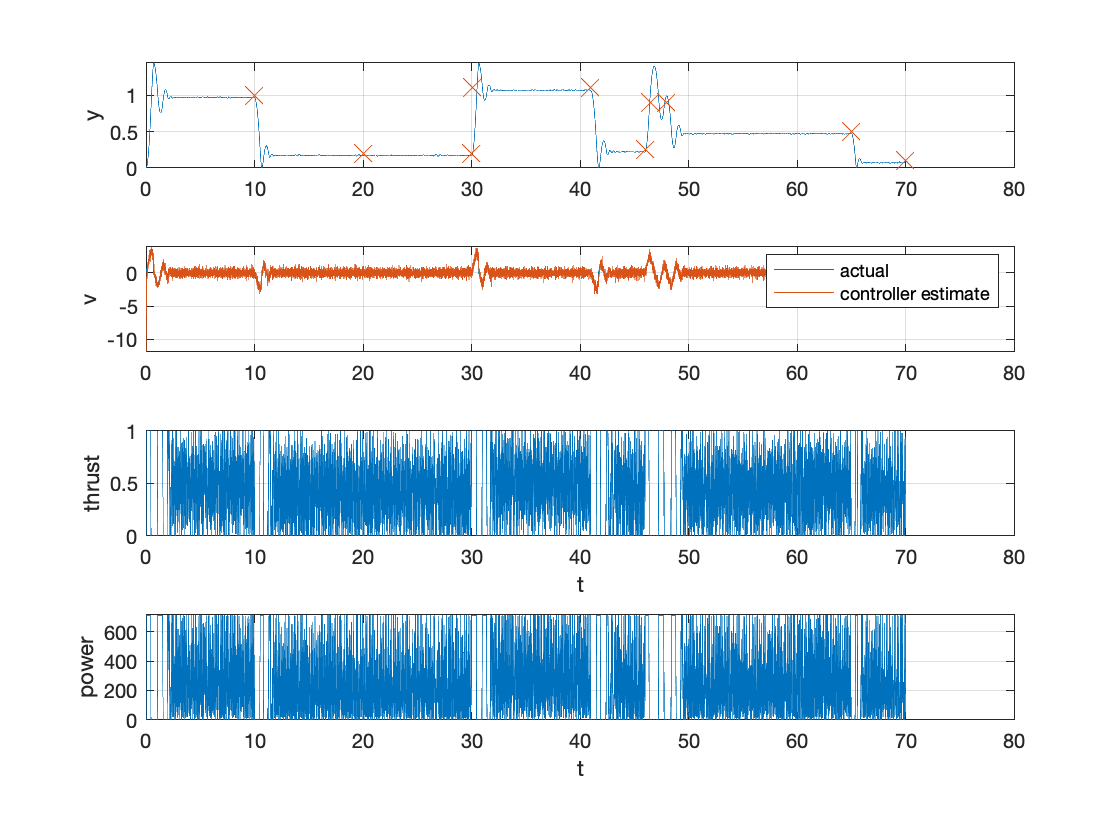

figure;

subplot(4, 1, 1);
plot(logs.t, logs.y);
grid on;
hold on;
scatter(waypoints.Time, waypoints.Data, 150, 'x');
%plot(controller.logs.t, controller.logs.y_est);
%legend('actual', 'controller estimate')
ylabel('y')
hold off;

subplot(4, 1, 2);
plot(logs.t, logs.v);
grid on;
hold on;
p2 = plot(controller.logs.t, controller.logs.v_est);
legend('actual', 'controller estimate')
hold off
ylabel('v')

subplot(4, 1, 3);
plot(logs.t, logs.thrust);
grid on;
ylabel('thrust')
xlabel('t')

subplot(4, 1, 4);
plot(logs.t, logs.power);
grid on;
ylabel('power')
xlabel('t')


accuracy = calcAccuracy(logs, waypoints)

accuracy = 0.1402

energy_total = trapz(logs.t, logs.power)

energy_total = 1.7424e+04

n_pts = 30;
R_range = logspace(-4, -0.5, n_pts);
Q_temp = [0, 0; 0, 1];

energy = zeros(1, n_pts);
accuracy = zeros(1, n_pts);
if false
    parfor i = 1:numel(R_range)
        disp(i);
        r_sample = R_range(i);
        K_temp = lqr(t_dis, Q_temp, r_sample);
        [tmp1, tmp2] = oneRun(K_temp, sim_setup);
        
        accuracy(i) = tmp1;
        energy(i) = tmp2;
    end
end

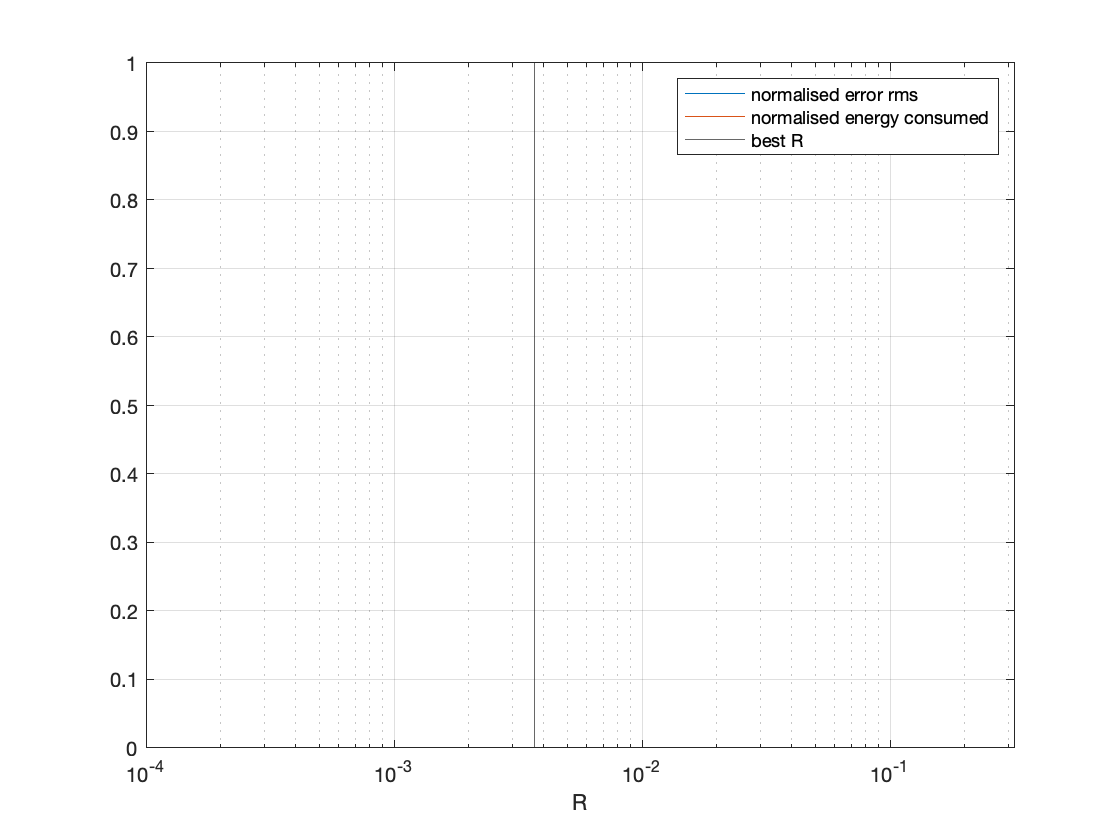

figure
semilogx(R_range, accuracy/mean(accuracy));
hold on;
semilogx(R_range, energy/mean(energy));
xlim([10^-4, 10^-0.5])
xline(0.0037);
legend('normalised error rms', 'normalised energy consumed', 'best R')
xlabel('R')
grid
hold off;


valid_range = R_range > 1E-3;

valid_R = R_range(valid_range);
[minval, minidx] = min(accuracy(valid_range))

minval = 0

minidx = 1

best_R = valid_R(minidx)

best_R = 0.0012

if true
[exp_acc, exp_energy] = manyRuns(K, sim_setup)
end

Starting parallel pool (parpool) using the 'local' profile ...
Connected to the parallel pool (number of workers: 8).
     6

     1

     4

     2

     5

     8

     3

     7

    16

    20

    10

    12

    18

    14

    24

    22

    15

    19

     9

    11

    17

    13

    23

    21

    26

    25

    27

    28

    29

    31

    30

    32



function accel = accelerationFunction(thrust, y, v, ss) % Calculates acceleration in kgms^-2, +ve up
% TODO: Add weight of the cable track as a function of y
    global thrust_buffer;
    if size(thrust_buffer, 2) == 0
        thrust_actual = thrust;
    else
        thrust_actual = thrust_buffer(end);
        thrust_buffer = circshift(thrust_buffer, 1);
        thrust_buffer(1) = thrust;
    end
    thrust_actual = thrust;
    thrust_term = ss.Fit_thrust(thrust_actual*100)*ss.g*2;
    cable_mass_kg = 0.19*(y + 0.5648);
    
    total_mass_kg = ss.quad_mass_kg + cable_mass_kg + ss.black_mass_kg + ss.white_mass_kg + ss.cart_mass_kg;
    grav_term = -(ss.quad_mass_kg + cable_mass_kg + ss.black_mass_kg + ss.white_mass_kg + ss.cart_mass_kg)*ss.g;
    total_weight_moment = -ss.quad_mass_kg*ss.g*ss.k1_m - cable_mass_kg*ss.g*ss.k2_m - ss.black_mass_kg*ss.g*ss.k3_m - ss.white_mass_kg*ss.g*ss.k4_m - ss.cart_mass_kg*ss.g*ss.k5_m;
    
    fun = @RopeTensionEqn;
    x0 = 3.924;
    rope_tension = fzero(fun, x0, [], ss, thrust, y);
    %rope_tension = 0;
    if v == 0
        rope_tension = ss.cart_mass_kg*ss.g;
        resultant = thrust_term*cosd(ss.theta_deg) + rope_tension + grav_term;
        ff1 = abs(ss.static_friction_coeff*(thrust_term*ss.thrust_centerline_distance_m*cosd(ss.theta_deg) + total_weight_moment + rope_tension*ss.k6_m)/ss.cart_height_m);
        ff2 = abs(ss.static_friction_coeff*(thrust_term*(ss.cart_height_m*tand(ss.theta_deg) - ss.thrust_centerline_distance_m)*cosd(ss.theta_deg) - total_weight_moment - rope_tension*ss.k6_m)/ss.cart_height_m);
        static_friction = ff1 + ff2;
        if abs(resultant) < static_friction
            accel = 0;
            return;
        else
            friction_term = -sign(resultant)*static_friction;
        end
    else
        ff1 = abs(ss.dyn_friction_coeff*(thrust_term*ss.thrust_centerline_distance_m*cosd(ss.theta_deg) + total_weight_moment + rope_tension*ss.k6_m)/ss.cart_height_m);
        ff2 = abs(ss.dyn_friction_coeff*(thrust_term*(ss.cart_height_m*tand(ss.theta_deg) - ss.thrust_centerline_distance_m)*cosd(ss.theta_deg) - total_weight_moment - rope_tension*ss.k6_m)/ss.cart_height_m);
        
        
        friction_term = -(ff1 + ff2)*sign(v);       
    end
    accel = (thrust_term*cosd(ss.theta_deg) + rope_tension + grav_term + friction_term) / total_mass_kg;
end

function Eqn = RopeTensionEqn(R, sim_setup, thrust, y)

    thrust_term = sim_setup.Fit_thrust(thrust*100)*sim_setup.g*2;
    cable_mass_kg = 0.19*(y + 0.5648);
    total_mass_kg = sim_setup.quad_mass_kg + cable_mass_kg + sim_setup.black_mass_kg + sim_setup.white_mass_kg + sim_setup.cart_mass_kg;
    total_weight_moment = -sim_setup.quad_mass_kg*sim_setup.g*sim_setup.k1_m - cable_mass_kg*sim_setup.g*sim_setup.k2_m - sim_setup.black_mass_kg*sim_setup.g*sim_setup.k3_m - sim_setup.white_mass_kg*sim_setup.g*sim_setup.k4_m - sim_setup.cart_mass_kg*sim_setup.g*sim_setup.k5_m;
    
    N1 = (thrust_term*sim_setup.thrust_centerline_distance_m*cosd(sim_setup.theta_deg) + total_weight_moment + R*sim_setup.k6_m)/sim_setup.cart_height_m;
    N2 = (thrust_term*(sim_setup.cart_height_m*tand(sim_setup.theta_deg) - sim_setup.thrust_centerline_distance_m)*cosd(sim_setup.theta_deg) - total_weight_moment - R*sim_setup.k6_m)/sim_setup.cart_height_m;
    N3 = (sim_setup.cart_mass_kg*sim_setup.g*sim_setup.k5_m - R*sim_setup.k6_m)/sim_setup.cart_height_m;
    N4 = (R*sim_setup.k6_m - sim_setup.cart_mass_kg*sim_setup.g*sim_setup.k5_m)/sim_setup.cart_height_m;
    
    Eqn = (sim_setup.cart_mass_kg*sim_setup.g - R - abs(sim_setup.dyn_friction_coeff*N3) - abs(sim_setup.dyn_friction_coeff*N4))/sim_setup.cart_mass_kg - (thrust_term*cosd(sim_setup.theta_deg) + R - total_mass_kg*sim_setup.g - abs(sim_setup.dyn_friction_coeff*N1) - abs(sim_setup.dyn_friction_coeff*N2))/total_mass_kg;

end

function rms_accuracy = calcAccuracy(logs, waypoints)
    [~, time_indices] = min(abs(logs.t' - waypoints.Time), [], 2);
    prev_idx = 1;
    err = 0;
    
    for idx_num = 1:numel(time_indices)
        idx = time_indices(idx_num);
        err = err + sum((logs.y(prev_idx:idx) - waypoints.Data(idx_num)).^2);
        prev_idx = idx;
    end
    
    %accuracies = waypoints.Data - logs.y(time_indices)
    %accuracy = logs.y - waypoints.Data
    %rms_accuracy = sqrt(mean(accuracies.^2));
    rms_accuracy = sqrt(err/numel(logs.t));
end

function randomWaypoints = randomTrack()
    n = randi([5, 15]);
    rand_height = @()(0-1.44).*rand() + 1.44;
    times = zeros(1, n);
    heights = zeros(1, n);
    
    times(1) = randi([0, 4]);
    heights(1) = rand_height();
    
    for idx = 2:n
        times(idx) = times(idx - 1) + randi([1, 5]);
        heights(idx) = rand_height();
    end
    
    randomWaypoints = timeseries(heights, times);
end

function power = powerFunction(thrust, ss)
    power = ss.Fit_power(thrust*100)*2;
end

function [accuracy, energy] = manyRuns(gains, ss)

    n = 40;
    accs = zeros(1, n);
    energies = zeros(1, n);
    parfor i = 1:n
        [tmp1, tmp2] = oneRun(gains, ss);
        disp(i);
        accs(i) = tmp1;
        energies(i) = tmp2;
    end
    
    accuracy = mean(accs);
    energy = mean(energies);
end

function [accuracy, energy] = oneRun(gains, ss)
    waypoints = randomTrack();
    waypoints = timeseries([1, 0.2, 0.2, 1.1, 1.1, 0.25, 0.9, 0.9, 0.5, 0.1], [10, 20, 30, 30.1, 41, 46, 46.5, 48, 65, 70]);
    if true
        controller = LQRController(gains, waypoints);
    else
        controller = ControlSystem([gains.p, gains.i, gains.d], waypoints);
    end
    
    T_max = max(waypoints.Time);
    dt = 5E-4;
    max_y_m = 1.44;
    motor_esc_delay = 0;
    % Initial position and acceleration
    y0 = 0;
    v0 = 0;
    
    y = y0;
    v = v0;
    
    global thrust_buffer;
    thrust_buffer = zeros(1, round(motor_esc_delay/dt));
    
    t_arr = 0:dt:T_max;

    logs.t = zeros(numel(t_arr), 1);
    logs.y = zeros(numel(t_arr), 1);
    logs.v = zeros(numel(t_arr), 1);
    logs.thrust = zeros(numel(t_arr), 1);
    logs.power = zeros(numel(t_arr), 1);
    
    Ts = 5E-3;
    steps_per_control = Ts/dt;
    
    t = 0;
    for t_idx = 1:round(numel(t_arr) / steps_per_control)
        
        thrust = controller.calculate(y, t);
        for i = 1:steps_per_control
            accel = accelerationFunction(thrust, y, v, ss);
            power = powerFunction(thrust, ss);
            
            y = y + v*dt;
            v = v + accel*dt;
            t = t + dt;
            
            % Make sure to not fall through the floor
            if y <= 0
                y = 0;
                v = max(0, v); % make sure v is not negative
            end
            
            if y >= max_y_m
                y = max_y_m;
                v = min(0, v); % make sure v is only negative
            end
            
            logs.t(t_idx*steps_per_control + i - 1) = t;
            logs.y(t_idx*steps_per_control + i - 1) = y;
            logs.v(t_idx*steps_per_control + i - 1) = v;
            logs.thrust(t_idx*steps_per_control + i - 1) = thrust;
            logs.power(t_idx*steps_per_control + i - 1) = power;
        end
    end
    
    accuracy = calcAccuracy(logs, waypoints);
    energy = trapz(logs.t, logs.power);
end